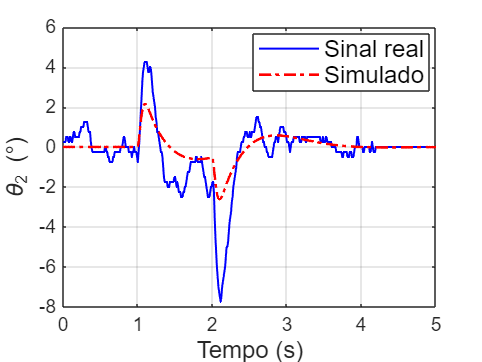

clc;
close all;

%% -------------------------------------------------------------
%  Carregamento dos dados experimentais e de simulação
% --------------------------------------------------------------
data = load('data_log_pulse.txt');   % Dados reais registrados

% Intervalo de amostragem a ser analisado
idx_inicial = 1;
idx_final   = 3000;

% Janela de visualização (em segundos)
t_min = 0;
t_max = 5;

%% -------------------------------------------------------------
%  Extração e pré-processamento dos sinais reais
% --------------------------------------------------------------
tempo_real     = data(idx_inicial:idx_final, 1) - 21;             % Tempo (s)
theta1_real    = data(idx_inicial:idx_final, 2) * 57.296 - 17;    % Ângulo da haste (°)
theta2_real    = data(idx_inicial:idx_final, 3) * 57.296 - 0.25;  % Ângulo do pêndulo (°)
theta1dot_real = data(idx_inicial:idx_final, 4) * 57.296;         % Velocidade da haste (°/s)
theta2dot_real = data(idx_inicial:idx_final, 5) * 57.296;         % Velocidade do pêndulo (°/s)
u_real         = -data(idx_inicial:idx_final, 6) + 0.1;           % Ação de controle (V)
d_real         = data(idx_inicial:idx_final, 7) / 21.25;          % Distúrbio (V)

tempo_real = tempo_real + 1;

%% -------------------------------------------------------------
%  Extração dos sinais simulados (estrutura gerada pelo Simulink)
% --------------------------------------------------------------
tempo_sim = out.tout;
theta1_sim    = out.yout{1}.Values.Data;
theta2_sim    = out.yout{2}.Values.Data;
theta1dot_sim = out.yout{3}.Values.Data;
theta2dot_sim = out.yout{4}.Values.Data;
u_sim         = out.yout{5}.Values.Data;
d_sim         = out.yout{6}.Values.Data;

%% -------------------------------------------------------------
%  Gráfico 1 – Ângulo do pêndulo (Theta 2)
% --------------------------------------------------------------
figure;
plot(tempo_real, theta2_real, 'b', 'LineWidth', 1);
hold on;
plot(tempo_sim, theta2_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('\theta_2 (°)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([t_min t_max]);
hold off;

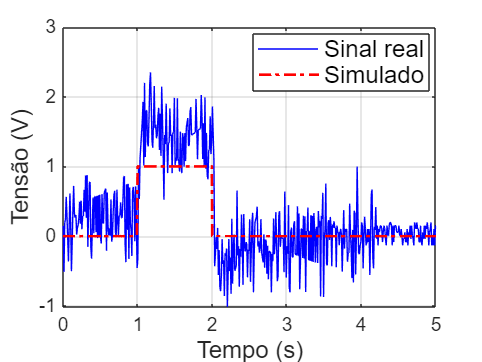


%% -------------------------------------------------------------
%  Gráfico 2 – Ação de controle (Tensão)
% --------------------------------------------------------------
figure;
plot(tempo_real, u_real, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, u_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Tensão (V)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([t_min t_max]);
hold off;

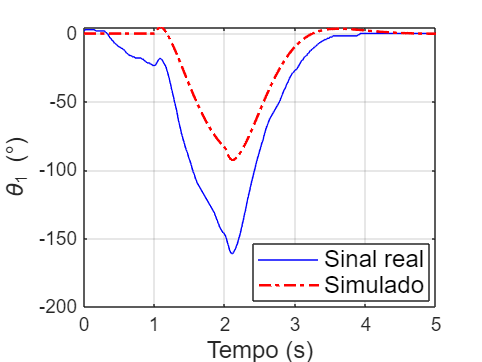


%% -------------------------------------------------------------
%  Gráfico 3 – Ângulo da haste (Theta 1)
% --------------------------------------------------------------
figure;
plot(tempo_real, theta1_real, 'b', 'LineWidth', 0.5);
hold on;
plot(tempo_sim, theta1_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('\theta_1 (°)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([t_min t_max]);
hold off;

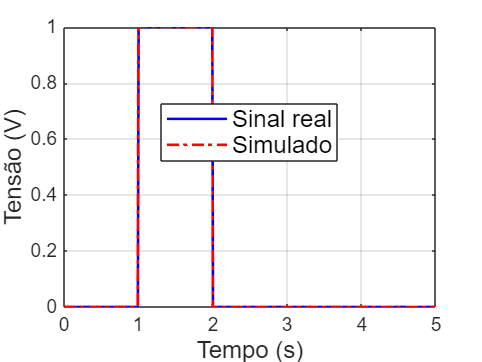


%% -------------------------------------------------------------
%  Gráfico 4 – Sinal de distúrbio
% --------------------------------------------------------------
figure;
plot(tempo_real, d_real, 'b', 'LineWidth', 1.3);
hold on;
plot(tempo_sim, d_sim, '-.r', 'LineWidth', 1.3);
xlabel('Tempo (s)', 'FontSize', 12)
ylabel('Tensão (V)', 'FontSize', 12)
legend('Sinal real', 'Simulado', 'Location', 'best', 'FontSize', 12)
grid on;
xlim([t_min t_max]);
hold off;